# Create Presentation Using Default Formatting

When you create a presentation container and do not specify a template, the template that comes with the PPT API defines the default style of the slides. You can override the default style for individual slides by using format properties and objects.

Import the PPT package so that you do not have to use  long, fully qualified names for the PPT API classes.

import mlreportgen.ppt.*

Create an `mlreportgen.ppt.Presentation` object to contain the slides. Do not specify a template. Add a slide for the title and a slide for text.

ppt = Presentation('myFirstPresentation.pptx');
open(ppt);

titleSlide = add(ppt,'Title Slide');
textSlide  = add(ppt,'Title and Content');

Specify a title for the presentation. Make the title red by creating the title as an `mlreportgen.ppt.Paragraph` object and setting the `FontColor` format property. 

paraObj = Paragraph('My First Presentation');
paraObj.FontColor = 'red';
replace(titleSlide,'Title',paraObj);

Add content to the second slide.

replace(textSlide,'Content',{'Subject A','Subject B','Subject C'});

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the generated presentation:

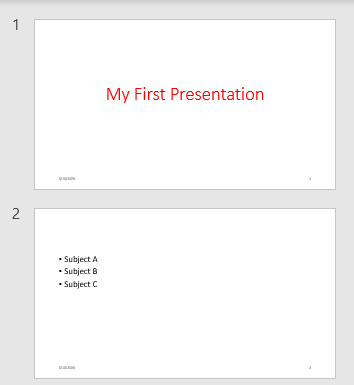

*Copyright 2019 The MathWorks, Inc.*